clear all;
close all;
clc;

urate = readtable("CAUR.csv");
BAA = readtable('BAA.csv');
AAA = readtable('AAA.csv');

urate.date = datetime(urate.observation_date);
urate.urate = urate.CAUR;

BAA.Properties.VariableNames = {'date', 'BAA'};
AAA.Properties.VariableNames = {'date', 'AAA'};
BAA.date = datetime(BAA.date);
AAA.date = datetime(AAA.date);

% use BAA and AAA，calculating junk spread
spread = innerjoin(BAA, AAA, 'Keys', 'date');
spread.junk_spread = spread.BAA - spread.AAA;

% UR and junk spread
merged_data = innerjoin(urate(:, {'date', 'urate'}), spread(:, {'date', 'junk_spread'}), 'Keys', 'date');

% merged table
writetable(merged_data, 'merged_data.csv');

% ADF unit root test
data = readtable("merged_data.csv");

y = data.urate;

% ADF test: with intercept, without trend, and have 12 lags
[h, pValue, stat, cValue, reg] = adftest(y, Model="ARD", lags=11);
fprintf("\n--- ADF Test: Model = ARD, lags = 12 ---\n");


--- ADF Test: Model = ARD, lags = 12 ---


fprintf("rejecting unit root or not: %d \n", h);

rejecting unit root or not: 1 


fprintf("ADF result: %.4f\n", stat);

ADF result: -3.2964


fprintf("p-value: %.4f\n", pValue);

p-value: 0.0156


y = data.junk_spread;

% ADF test: with intercept, without trend, and have 12 lags
[h, pValue, stat, cValue, reg] = adftest(y, Model="ARD", lags=11);

fprintf("\n--- ADF Test: Model = ARD, lags = 12 ---\n");


--- ADF Test: Model = ARD, lags = 12 ---


fprintf("rejecting unit root or not: %d \n", h);

rejecting unit root or not: 1 


fprintf("ADF result: %.4f\n", stat);

ADF result: -3.5921


fprintf("p-value: %.4f\n", pValue);

p-value: 0.0066


Granger test of spread on Unemployment

maxLags=12;
% Run Granger causality test for each lag
for p = 1:maxLags
% Test: Does unemployment Granger-cause junk spread?
[h2, pval2, stat2] = gctest(spread.junk_spread, merged_data.urate, 'NumLags', p);
pval_urate_to_junk(p) = pval2;
stat_urate_to_junk(p) = stat2;
end

h=1, we reject null hypothesis

p-value = 2.72279826250296e-06 for p=12

Use AIC to find p and q

data = readtable("merged_data.csv");
urate = data.urate;
spread = data.junk_spread;
T = length(urate);

% p=12 q=12 by convention
maxP = 12;
maxQ = 12;

aic_matrix = NaN(maxP+1, maxQ+1);  % p = 0..12, q = 0..12

% consider all combination of (p, q) and calculate their AIC
for p = 1:maxP
    for q = 0:maxQ
        Y = urate(maxP+1:end);
        X = ones(T - maxP, 1);

        for i = 1:p
            X = [X, urate(maxP+1-i:end-i)];
        end

        for j = 1:q
            X = [X, spread(maxP+1-j:end-j)];
        end

        valid = all(~isnan([Y X]), 2);
        Y_valid = Y(valid);
        X_valid = X(valid, :);

        if rank(X_valid) < size(X_valid, 2)
            continue;
        end

        try
            mdl = fitlm(X_valid, Y_valid);
            aic_matrix(p+1, q+1) = mdl.ModelCriterion.AIC;
        catch
            aic_matrix(p+1, q+1) = NaN;
        end
    end
end

% AIC table
fprintf('\nAIC Table for ADL(p, q):\n');


AIC Table for ADL(p, q):


for q = 0:maxQ
    fprintf(' q=%2d   ', q);
end

 q= 0    q= 1    q= 2    q= 3    q= 4    q= 5    q= 6    q= 7    q= 8    q= 9    q=10    q=11    q=12   

fprintf('\n');

for p = 0:maxP
    fprintf('p=%2d ', p);
    for q = 0:maxQ
        if ~isnan(aic_matrix(p+1,q+1))
            fprintf('%8.2f ', aic_matrix(p+1,q+1));
        else
            fprintf('   ---   ');
        end
    end
    fprintf('\n');
end

p= 0 

   ---      ---      ---      ---      ---      ---      ---      ---      ---      ---      ---      ---      ---   

p= 1 

  796.52   780.58   766.39   766.33   768.06   770.06   770.92   771.82   773.81   775.75   777.74   779.17   781.17 

p= 2 

  776.53   765.60   756.46   754.73   756.43   758.40   759.09   760.31   762.31   764.13   766.10   767.59   769.52 

p= 3 

  776.33   763.94   755.71   754.99   756.47   758.43   759.27   760.58   762.57   764.37   766.36   767.80   769.74 

p= 4 

  774.43   763.45   754.66   754.32   756.14   757.99   758.86   760.06   762.03   763.89   765.89   767.44   769.36 

p= 5 

  775.16   763.14   754.45   753.79   755.68   757.67   758.90   760.07   762.06   763.96   765.94   767.54   769.49 

p= 6 

  774.94   761.55   753.41   752.73   754.69   756.65   758.34   759.84   761.82   763.75   765.75   767.42   769.35 

p= 7 

  776.66   763.55   755.41   754.72   756.68   758.63   760.30   761.84   763.82   765.75   767.75   769.41   771.35 

p= 8 

  778.35   765.54   757.38   756.68   758.63   760.59   762.27   763.82   765.80   767.71   769.71   771.38   773.31 

p= 9 

  778.28   766.43   757.79   757.15   759.11   761.09   762.77   764.42   766.41   768.15   770.10   771.75   773.66 

p=10 

  780.23   768.43   759.77   759.15   761.11   763.09   764.77   766.42   768.41   770.15   772.10   773.74   775.65 

p=11 

  781.27   769.87   760.78   760.31   762.24   764.23   765.88   767.59   769.58   771.38   773.36   775.16   776.98 

p=12 

  782.80   771.60   762.31   761.97   763.90   765.89   767.55   769.24   771.24   773.04   775.02   776.79   778.50 

% choose p and q minimizing AIC value
[minAIC, idx] = min(aic_matrix(:));
[optP_idx, optQ_idx] = ind2sub(size(aic_matrix), idx);
optP = optP_idx - 1;
optQ = optQ_idx - 1;
fprintf('\n Best：p = %d, q = %d，AIC = %.2f\n', optP, optQ, minAIC);


 Best：p = 6, q = 3，AIC = 752.73


3.3 Forecast using ADL(6,3)

urate = data.urate;
spread = data.junk_spread;
date = data.date;
T = length(urate);
h_max = 12;
date_forecast = date(end) + calmonths(1:h_max)';

unrate_f=zeros(12,1); unrate_fi=zeros(12,2);
T=590;
for h=1:12
X=lagmatrix(urate,h:h+5);
X_spread=lagmatrix(spread,h:h+2);
mdldl=fitlm([X, X_spread],urate);
[unrate_p,unrate_pi] = predict(mdldl,[fliplr(urate(T-5:T)') fliplr(spread(T-2:T)')],'Prediction','observation','Alpha',0.1);
unrate_f(h,1)=unrate_p;
unrate_fi(h,:)=unrate_pi;
if i==1
        mdl1all=mdldl
    end
if i==2
        mdl2all=mdldl
    end
if i==3
        mdl3all=mdldl
    end
if i==4
        mdl4all=mdldl
    end
if i==5
        mdl5all=mdldl
    end
if i==6
        mdl6all=mdldl
    end
if i==7
        mdl7all=mdldl
    end
if i==8
        mdl8all=mdldl
    end
if i==9
        mdl9all=mdldl
    end
if i==10
        mdl10all=mdldl
    end
if i==11
        mdl11all=mdldl
    end
if i==12
        mdl12all=mdldl
    end
end

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate        SE        tStat        pValue   
                   _________    ________    ________    ___________

    (Intercept)     0.041594    0.075428     0.55143        0.58155
    x1                1.1321    0.042178      26.841    1.9523e-103
    x2              -0.23515    0.064133     -3.6666     0.00026867
    x3               0.13859    0.064774      2.1395       0.032815
    x4              -0.12206    0.063934     -1.9092       0.056739
    x5             -0.018788    0.063104    -0.29773        0.76602
    x6              0.072019    0.040909      1.7605       0.078858
    x7  

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     0.14048     0.11689     1.2018       0.22992
    x1               1.0329     0.06526     15.828    4.4593e-47
    x2             -0.11509     0.09923    -1.1598       0.24661
    x3             0.041797     0.10022    0.41706       0.67679
    x4             -0.17407    0.098919    -1.7598      0.078982
    x5             0.064303    0.097638    0.65859       0.51042
    x6             0.075983    0.063304     1.2003       0.23052
    x7               1.029

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)      0.25488     0.14392       1.771      0.077097
    x1                1.0376    0.080222      12.934    9.5082e-34
    x2              -0.18425     0.12198     -1.5105       0.13147
    x3             -0.023262      0.1232    -0.18882        0.8503
    x4              -0.08705      0.1216    -0.71588       0.47436
    x5              0.085243     0.12002     0.71021       0.47786
    x6              0.058444    0.077818     0.75104       0.45294
    x7         </

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)      0.38764     0.16717      2.3189      0.020752
    x1               0.97663    0.093031      10.498    1.0803e-23
    x2              -0.25355     0.14145     -1.7925      0.073581
    x3              0.068721     0.14286     0.48102       0.63068
    x4             -0.082478     0.14102    -0.58489       0.55885
    x5               0.12619     0.13919     0.90662       0.36499
    x6              0.010131    0.090253     0.11225       0.91066
    x7         </

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                    Estimate        SE         tStat         pValue  
                   ___________    _______    __________    __________

    (Intercept)        0.52989    0.18625        2.8451     0.0045994
    x1                 0.83554    0.10348        8.0743    4.0515e-15
    x2                -0.14578    0.15734      -0.92654       0.35456
    x3                0.068431    0.15891       0.43062       0.66691
    x4               -0.039007    0.15686      -0.24867        0.8037
    x5                0.087217    0.15482       0.56333       0.57343
    x6             -0.00039014     0.1004    -0.0038859        0.996

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)      0.67892    0.19988      3.3966    0.00072987
    x1               0.78496     0.1109      7.0781    4.3191e-12
    x2              -0.11406    0.16862    -0.67643       0.49904
    x3              0.094375     0.1703     0.55416       0.57969
    x4             -0.069962     0.1681     -0.4162       0.67742
    x5               0.11174    0.16592      0.6735        0.5009
    x6             -0.037203     0.1076    -0.34577       0.72964
    x7           

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)      0.83539    0.21156      3.9487    8.8443e-05
    x1               0.76265    0.11719      6.5076    1.6784e-10
    x2              -0.07366    0.17819    -0.41338       0.67948
    x3              0.049747    0.17997     0.27642       0.78233
    x4             -0.048068    0.17764    -0.27059        0.7868
    x5               0.10783    0.17534     0.61499       0.53881
    x6             -0.065111    0.11372    -0.57255       0.56717
    x7           

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       1.0071    0.22257      4.5248    7.3676e-06
    x1               0.77726     0.1231      6.3139    5.4957e-10
    x2              -0.11439    0.18717    -0.61116       0.54134
    x3              0.073827    0.18904     0.39053       0.69629
    x4             -0.059352     0.1866    -0.31807       0.75055
    x5                0.1122    0.18418      0.6092       0.54264
    x6             -0.092931    0.11945    -0.77796       0.43691
    x7           

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       1.1775    0.23348      5.0433    6.1719e-07
    x1               0.75188    0.12892      5.8321    9.2094e-09
    x2             -0.099721    0.19601    -0.50875       0.61112
    x3              0.075078    0.19797     0.37923       0.70466
    x4              -0.05698    0.19541    -0.29159       0.77071
    x5               0.08854    0.19287     0.45906       0.64637
    x6             -0.098153     0.1251    -0.78461       0.43301
    x7           

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       1.3565    0.24328      5.5759    3.8203e-08
    x1                 0.742    0.13411      5.5328    4.8274e-08
    x2             -0.095268     0.2039    -0.46722       0.64052
    x3              0.074221    0.20595     0.36039       0.71869
    x4             -0.089125    0.20328    -0.43844       0.66123
    x5               0.13133    0.20063     0.65456       0.51302
    x6              -0.13907    0.13014     -1.0687       0.28568
    x7           

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       1.5519     0.2533      6.1268    1.6832e-09
    x1               0.73184    0.13941      5.2496    2.1625e-07
    x2             -0.088564    0.21195    -0.41785       0.67622
    x3              0.039403    0.21407     0.18407       0.85403
    x4             -0.050337    0.21129    -0.23823       0.81179
    x5              0.094445    0.20855     0.45287       0.65082
    x6              -0.14036    0.13527     -1.0376       0.29992
    x7           

mdl12all = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      1.7548    0.26293      6.6743     5.959e-11
    x1              0.72771    0.14447      5.0371    6.3743e-07
    x2             -0.12018    0.21965    -0.54714        0.5845
    x3             0.075659    0.22184     0.34105       0.73319
    x4             -0.09091    0.21896    -0.41518       0.67816
    x5              0.10938    0.21612     0.50608         0.613
    x6             -0.15351    0.14021     -1.0949       0.27402
    x7               1.769

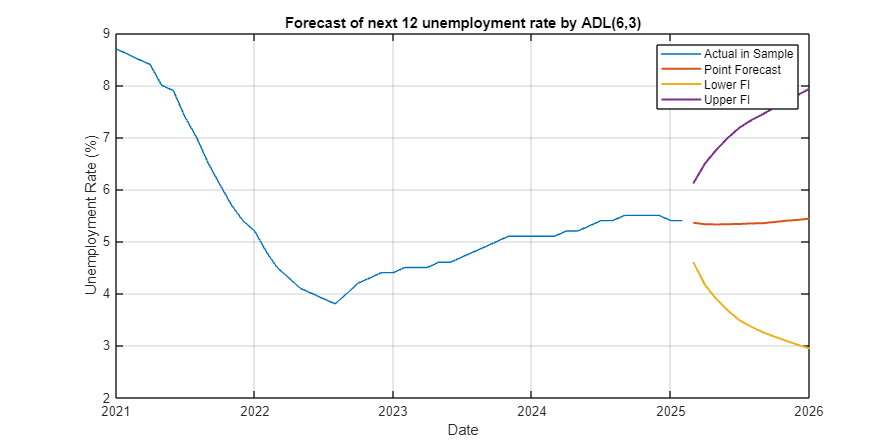

data114 = merged_data(merged_data.date >= datetime(2021,1,1), :);
figure('Position', [100, 100, 900, 450]);
plot(data114.date,data114.urate);
hold on;
plot(date_forecast,unrate_f,'LineWidth',1.5);
hold on;
plot(date_forecast,unrate_fi,'LineWidth',1.5);
title('Forecast of next 12 unemployment rate by ADL(6,3)');
legend('Actual in Sample', 'Point Forecast','Lower FI','Upper FI');
xlabel('Date'); ylabel('Unemployment Rate (%)');
grid on; datetick('x', 'yyyy', 'keepticks');

Part 4: Consider whether deleting COVID data is good for forecasting and pick the model under COVID-reduced data 

data = readtable('merged_data.csv');
urate = data.urate;
spread = data.junk_spread;
date = datetime(data.date);
T = length(urate);

%% Step 1.5: delete uncommon data from 2020-04 ~ 2020-07, in which there are extreme COVID shock
shock_dates = [ ...
    datetime(2020,4,1), ...
    datetime(2020,5,1), ...
    datetime(2020,6,1), ...
    datetime(2020,7,1) ...
];
valid_mask = ~ismember(date, shock_dates);
urate = urate(valid_mask);
spread = spread(valid_mask);
T = length(urate);  


maxP = 12;
maxQ = 12;
aic_matrix = NaN(maxP+1, maxQ+1);  


for p = 1:maxP
    for q = 0:maxQ
        Y = urate(maxP+1:end);  
        X = ones(T - maxP, 1);  
        
        for i = 1:p
            X = [X, urate(maxP+1-i:end-i)];
        end
        
        for j = 1:q
            X = [X, spread(maxP+1-j:end-j)];
        end

        valid = all(~isnan([Y X]), 2);
        Y_valid = Y(valid);
        X_valid = X(valid, :);

        if rank(X_valid) < size(X_valid, 2)
            continue;
        end

        try
            mdl = fitlm(X_valid, Y_valid);
            aic_matrix(p+1, q+1) = mdl.ModelCriterion.AIC;
        catch
            aic_matrix(p+1, q+1) = NaN;
        end
    end
end

fprintf('\nAIC Table for ADL(p, q):\n');


AIC Table for ADL(p, q):


for q = 0:maxQ
    fprintf(' q=%2d   ', q);
end

 q= 0    q= 1    q= 2    q= 3    q= 4    q= 5    q= 6    q= 7    q= 8    q= 9    q=10    q=11    q=12   

fprintf('\n');

for p = 0:maxP
    fprintf('p=%2d ', p);
    for q = 0:maxQ
        if ~isnan(aic_matrix(p+1,q+1))
            fprintf('%8.2f ', aic_matrix(p+1,q+1));
        else
            fprintf('   ---   ');
        end
    end
    fprintf('\n');
end

p= 0 

   ---      ---      ---      ---      ---      ---      ---      ---      ---      ---      ---      ---      ---   

p= 1 

  291.94   259.25   244.91   244.36   245.80   247.76   249.75   251.37   253.31   255.31   257.10   258.48   260.38 

p= 2 

  288.38   259.53   244.71   243.02   244.29   246.28   248.28   249.82   251.75   253.75   255.58   257.07   259.02 

p= 3 

  286.87   260.68   245.84   244.37   245.88   247.86   249.86   251.38   253.33   255.33   257.17   258.67   260.63 

p= 4 

  281.49   259.27   244.53   243.22   244.58   246.53   248.52   249.94   251.91   253.90   255.73   257.26   259.24 

p= 5 

  275.86   256.98   241.43   240.11   241.39   243.38   245.23   246.85   248.84   250.82   252.73   254.24   256.22 

p= 6 

  274.91   257.55   241.22   240.14   241.42   243.42   245.32   246.45   248.41   250.38   252.30   253.91   255.88 

p= 7 

  274.48   258.16   240.90   240.13   241.29   243.29   245.21   246.47   248.46   250.45   252.40   254.04   256.03 

p= 8 

  274.28   258.65   240.43   240.01   240.99   242.99   244.91   246.20   248.20   250.03   251.93   253.62   255.62 

p= 9 

  273.94   258.77   239.80   239.72   240.46   242.45   244.41   245.68   247.68   249.57   251.57   253.16   255.16 

p=10 

  275.85   260.73   241.71   241.67   242.37   244.36   246.32   247.61   249.61   251.51   253.51   255.14   257.14 

p=11 

  276.47   261.44   241.80   241.81   242.28   244.23   246.22   247.65   249.64   251.53   253.53   255.07   257.00 

p=12 

  278.18   263.16   243.63   243.58   244.06   246.02   248.01   249.38   251.38   253.25   255.25   256.80   258.71 

[minAIC, idx] = min(aic_matrix(:));
[optP_idx, optQ_idx] = ind2sub(size(aic_matrix), idx);
optP = optP_idx - 1;
optQ = optQ_idx - 1;
fprintf('\n Best：p = %d, q = %d，AIC = %.2f\n', optP, optQ, minAIC);


 Best：p = 9, q = 3，AIC = 239.72


My best model is ADL(9,3) after deleting covid, Now we compare this ADL(9,3) to the previous ADL(6,3)

Because they are based on different dataset. Suggested by the lecture, we use PLS to compare those 2 forecasting model.

%PLS of the model ADL(6,3) based on the whole dataset
data = readtable('merged_data.csv');  
date = datetime(data.date);          
urate = data.urate;                 
spread = data.junk_spread; 

% Set psudo-forecast period from 2022-01 to 2025-02 for PLS
start_date = datetime(2022,1,1);
end_date = datetime(2025,2,1);
forecast_idx = find(date >= start_date & date <= end_date);

y_hat = nan(length(forecast_idx), 1); % predicted value
y_true = urate(forecast_idx); % actual value

p = 6;
q = 3;

for i = 1:length(forecast_idx)
    t = forecast_idx(i);
    
    if t <= max(p, q)
        continue;
    end

    y_train = urate(1:t-1);
    x_train = spread(1:t-1);
    T_train = length(y_train);

    X = [];
    Y = [];

    for j = max(p,q)+1:T_train
        row = [...
            y_train(j-1), y_train(j-2), y_train(j-3), y_train(j-4), y_train(j-5), y_train(j-6) ...
            x_train(j-1), x_train(j-2), x_train(j-3) ...
        ];
        X = [X; row];
        Y = [Y; y_train(j)];
    end

    beta = X \ Y;

    x_pred = [...
        urate(t-1), urate(t-2), urate(t-3), urate(t-4), urate(t-5), urate(t-6)...
        spread(t-1), spread(t-2), spread(t-3) ...
    ];

    y_hat(i) = x_pred * beta;
end

valid = ~isnan(y_hat);
pls = sqrt(mean((y_true(valid) - y_hat(valid)).^2));

fprintf('PLS for ADL(6,3) is %.4f\n', pls);

PLS for ADL(6,3) is 0.1452


On the other hand: 

%PLS of the model ADL(9,3)
data = readtable('merged_data.csv');
date = datetime(data.date);
urate = data.urate;
spread = data.junk_spread;


shock_months = [datetime(2020,4,1), datetime(2020,5,1), ...
                datetime(2020,6,1), datetime(2020,7,1)];
non_shock_mask = ~ismember(date, shock_months);
urate = urate(non_shock_mask);
spread = spread(non_shock_mask);
date = date(non_shock_mask);

% Set psudo-forecast period from 2022-01 to 2025-02 for PLS
forecast_start = datetime(2022,1,1);
forecast_end   = datetime(2025,2,1);
forecast_idx = find(date >= forecast_start & date <= forecast_end);
y_true = urate(forecast_idx); % predicted value
y_hat = nan(length(forecast_idx), 1); % actual value

p = 9;
q = 3;

for i = 1:length(forecast_idx)
    t = forecast_idx(i);

    if t <= max(p, q)
        continue;
    end

    mask = date < date(t);
    y_train = urate(mask);
    x_train = spread(mask);

    X = [];
    Y = [];

    for j = max(p,q)+1:length(y_train)
        row = [...
            y_train(j-1), y_train(j-2), y_train(j-3), y_train(j-4), y_train(j-5),y_train(j-6),y_train(j-7),y_train(j-8),y_train(j-9)...
            x_train(j-1), x_train(j-2), x_train(j-3)];
        X = [X; row];
        Y = [Y; y_train(j)];
    end

    if length(Y) < 10
        continue;
    end

    beta = X \ Y;

    x_pred = [...
        urate(t-1), urate(t-2), urate(t-3), urate(t-4), urate(t-5), urate(t-6), urate(t-7), urate(t-8), urate(t-9)...
        spread(t-1), spread(t-2), spread(t-3)];
    y_hat(i) = x_pred * beta;
end

valid = ~isnan(y_hat);
pls = sqrt(mean((y_true(valid) - y_hat(valid)).^2));

fprintf('PLS for ADL(9,3) is %.4f\n', pls);

PLS for ADL(9,3) is 0.0991


Now we are forecasting by using ADL(9,3) based on COVID-reduced data

nocovid_unrate_f=zeros(12,1); nocovid_unrate_fi=zeros(12,2);
TT=586;
for h=1:12
X=lagmatrix(urate,h:h+8);
X_spread=lagmatrix(spread,h:h+2);
mdldl2=fitlm([X, X_spread],urate);
[unrate_p,unrate_pi] = predict(mdldl2,[fliplr(urate(TT-8:TT)') fliplr(spread(TT-2:TT)')],'Prediction','observation','Alpha',0.1);
nocovid_unrate_f(h,1)=unrate_p;
nocovid_unrate_fi(h,:)=unrate_pi;
if h==1
        mdl1COV=mdldl2
    end
if h==2
        mdl2COV=mdldl2
    end
if h==3
        mdl3COV=mdldl2
    end
if h==4
        mdl4COV=mdldl2
    end
if h==5
        mdl5COV=mdldl2
    end
if h==6
        mdl6COV=mdldl2
    end
if h==7
        mdl7COV=mdldl2
    end
if h==8
        mdl8COV=mdldl2
    end
if h==9
        mdl9COV=mdldl2
    end
if h==10
        mdl10COV=mdldl2
    end
if h==11
        mdl11COV=mdldl2
    end
if h==12
        mdl12COV=mdldl2
    end
end

mdl1COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)     0.047988    0.051014     0.94068       0.34727
    x1                1.0268    0.041951      24.476    1.0668e-90
    x2             -0.035842    0.059487    -0.60251       0.54708
    x3               0.04094    0.058519      0.6996       0.48447
    x4              0.023447    0.058565     0.40035       0.68905
    x5             -0.029894    0.058549    -0.51057       0.60985
    x6             0.0038572     0.05853    0.065902       0.94748
    

mdl2COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)      0.13949    0.073903      1.8875      0.059607
    x1                 1.031    0.060659      16.996    1.3403e-52
    x2             0.0077514    0.086013    0.090119       0.92822
    x3              0.051002    0.084609     0.60279       0.54689
    x4             -0.010789    0.084675    -0.12742       0.89865
    x5              -0.02917    0.084657    -0.34457       0.73055
    x6             0.0059959    0.084629     0.07085       0.94354
    

mdl3COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    ________    _________    __________

    (Intercept)       0.24781    0.091648        2.704     0.0070593
    x1                 1.0789    0.075074       14.372    4.0985e-40
    x2               0.018088     0.10645      0.16992       0.86514
    x3               0.014128     0.10472      0.13492       0.89273
    x4              -0.012239      0.1048     -0.11679       0.90707
    x5              -0.027214     0.10478     -0.25973       0.79517
    x6               0.015122     0.10474      0.14437     

mdl4COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                    Estimate         SE         tStat         pValue  
                   ___________    ________    __________    __________

    (Intercept)        0.36384     0.10826        3.3608    0.00083007
    x1                  1.1435    0.088508         12.92     1.293e-33
    x2                -0.02103      0.1255      -0.16757       0.86698
    x3                0.011843     0.12346      0.095926       0.92361
    x4              -0.0093598     0.12356     -0.075749       0.93965
    x5               -0.020527     0.12354      -0.16616       0.86809
    x6               -0.034416     0.12349 

mdl5COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    ________    _________    __________

    (Intercept)       0.48966     0.12473       3.9258     9.721e-05
    x1                 1.1744     0.10178       11.539    8.8211e-28
    x2              -0.024363     0.14433      -0.1688       0.86602
    x3               0.013895     0.14198     0.097863       0.92208
    x4             -0.0019166     0.14209    -0.013488       0.98924
    x5              -0.072688     0.14206     -0.51168       0.60908
    x6               0.003745     0.14201     0.026372     

mdl6COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)      0.61969    0.14045      4.4123    1.2277e-05
    x1                1.2114    0.11442      10.588    5.3448e-24
    x2             -0.028265    0.16225     -0.1742       0.86177
    x3              0.020464    0.15961     0.12822       0.89802
    x4             -0.053359    0.15973    -0.33406       0.73846
    x5             -0.037593     0.1597     -0.2354       0.81398
    x6             -0.065921    0.15964    -0.41293       0.67982
    x7   

mdl7COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate       SE         tStat        pValue  
                   _________    _______    _________    __________

    (Intercept)      0.75357    0.15578       4.8373    1.7046e-06
    x1                1.2593    0.12669       9.9402     1.518e-21
    x2             -0.036091    0.17967     -0.20088       0.84087
    x3             -0.030855    0.17672     -0.17459       0.86146
    x4             -0.017295    0.17687    -0.097786       0.92214
    x5              -0.11179    0.17683     -0.63221       0.52751
    x6             -0.060129    0.17677     -0.34015       0.73387
    

mdl8COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)      0.89554    0.17112      5.2334    2.3613e-07
    x1                1.3044    0.13894      9.3884    1.5418e-19
    x2             -0.088926    0.19702    -0.45135       0.65191
    x3             0.0041407     0.1938    0.021366       0.98296
    x4             -0.091227    0.19396    -0.47034        0.6383
    x5              -0.10828    0.19392     -0.5584        0.5768
    x6             -0.075818    0.19385    -0.39113       0.69585
    x7   

mdl9COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       1.0422    0.18624      5.5962    3.4429e-08
    x1                1.2899    0.15094      8.5455    1.2363e-16
    x2             -0.045455    0.21403    -0.21238       0.83189
    x3             -0.069745    0.21053    -0.33128       0.74056
    x4             -0.087702     0.2107    -0.41623        0.6774
    x5              -0.12334    0.21065    -0.58553       0.55843
    x6             -0.053622    0.21057    -0.25465       0.79908
    x7   

mdl10COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       1.1955    0.20021       5.971    4.2109e-09
    x1                1.3247    0.16194      8.1804    1.9394e-15
    x2              -0.12733    0.22963    -0.55451       0.57946
    x3             -0.067374    0.22588    -0.29828        0.7656
    x4              -0.10459    0.22605    -0.46269       0.64377
    x5              -0.10216    0.22599    -0.45207        0.6514
    x6             -0.051733    0.22591      -0.229       0.81895
    x7  

mdl11COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)        1.367    0.21452      6.3724    3.9186e-10
    x1                1.2859    0.17315      7.4265    4.2377e-13
    x2              -0.12995    0.24552    -0.52928       0.59683
    x3             -0.087189    0.24151    -0.36102       0.71822
    x4             -0.084637    0.24169    -0.35019       0.72633
    x5              -0.10284    0.24163    -0.42561       0.67055
    x6             -0.036221    0.24155    -0.14995       0.88086
    x7  

mdl12COV = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate       SE         tStat        pValue  
                   _________    _______    _________    __________

    (Intercept)       1.5418    0.22765       6.7726    3.2418e-11
    x1                1.2484    0.18336       6.8086    2.5744e-11
    x2              -0.15263    0.26001     -0.58703       0.55742
    x3             -0.070253    0.25575     -0.27469       0.78366
    x4             -0.087093    0.25595     -0.34028       0.73378
    x5             -0.087253    0.25589     -0.34098       0.73325
    x6             -0.011124    0.25579    -0.043488       0.96533
    


disp(mdl1COV);

Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)     0.047988    0.051014     0.94068       0.34727
    x1                1.0268    0.041951      24.476    1.0668e-90
    x2             -0.035842    0.059487    -0.60251       0.54708
    x3               0.04094    0.058519      0.6996       0.48447
    x4              0.023447    0.058565     0.40035       0.68905
    x5             -0.029894    0.058549    -0.51057       0.60985
    x6             0.0038572     0.05853    0.065902       0.94748
    x7    

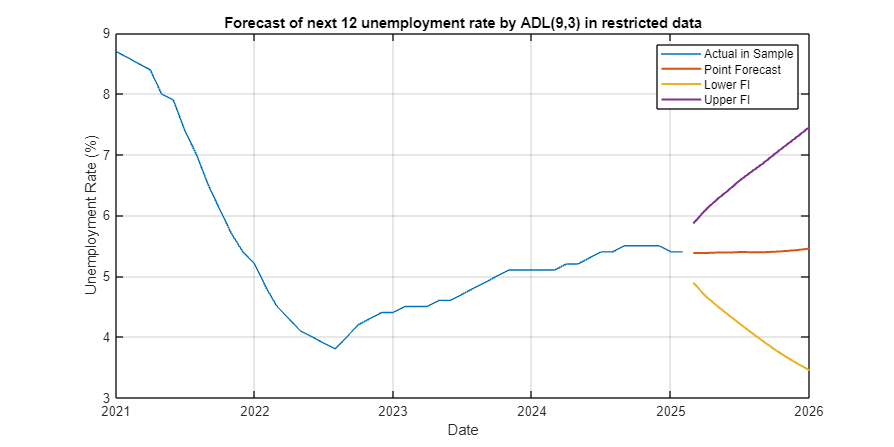

data114 = merged_data(merged_data.date >= datetime(2021,1,1), :);

figure('Position', [100, 100, 900, 450]);
plot(data114.date,data114.urate);
hold on;
plot(date_forecast,nocovid_unrate_f,'LineWidth',1.5);
hold on;
plot(date_forecast,nocovid_unrate_fi,'LineWidth',1.5);
title('Forecast of next 12 unemployment rate by ADL(9,3) in restricted data');
legend('Actual in Sample', 'Point Forecast','Lower FI','Upper FI');
xlabel('Date'); ylabel('Unemployment Rate (%)');
grid on; datetick('x', 'yyyy', 'keepticks');

data114 = merged_data(merged_data.date >= datetime(2024,1,1), :);
highlight_x = datetime(2025,3,1);  % March 2025
highlight_y = 5.3;

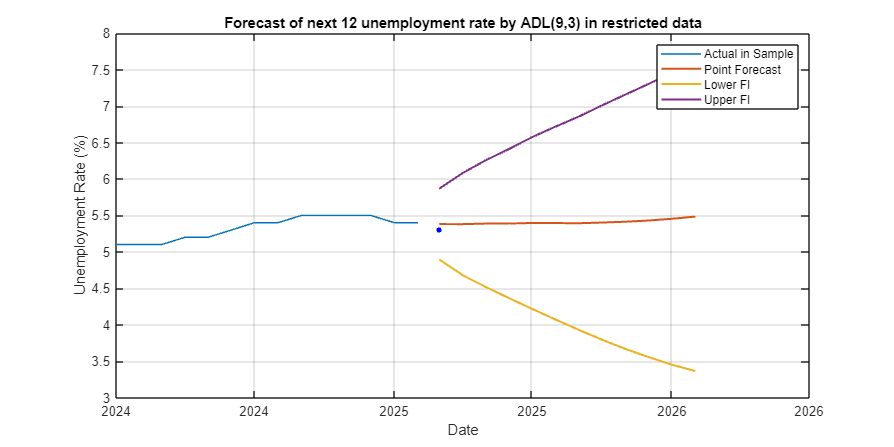

figure('Position', [100, 100, 900, 450]);
plot(data114.date,data114.urate);
hold on;
plot(date_forecast,nocovid_unrate_f,'LineWidth',1.5);
hold on;
plot(date_forecast,nocovid_unrate_fi,'LineWidth',1.5);
plot(highlight_x, highlight_y, 'bo', 'MarkerSize', 2, 'LineWidth', 2); 
title('Forecast of next 12 unemployment rate by ADL(9,3) in restricted data');
legend('Actual in Sample', 'Point Forecast','Lower FI','Upper FI');
xlabel('Date'); ylabel('Unemployment Rate (%)');
grid on; datetick('x', 'yyyy', 'keepticks');